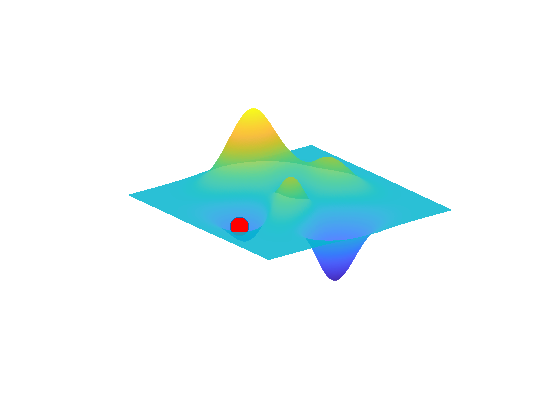

[sx,sy,sz] = peaks(500);

F = scatteredInterpolant(sx(:), sy(:), sz(:));
func = @(x, y)F(x, y) + 0.5;

nframes = 100;

% h = figure(Visible="off");
h = figure;

surf(sx,sy,sz,EdgeColor="none", FaceAlpha=0.85);
hold on
m = plot3(0.0, 0.0, func(0.0, 0.0) ,"o", ...
    "MarkerFaceColor","red", ...
    "MarkerSize",14);
axis off

xmin = min(sx, [], 'all');
xmax = max(sx, [], 'all');
ymin = min(sy, [], 'all');
ymax = max(sy, [], 'all');

fn = "bouncing.gif";
if exist(fn, 'file')
    delete(fn);
end
exportgraphics(h, fn, Resolution=150);


velocity = 1;
randPos = @()(rand()-0.5) * velocity;
coerce = @(val, vmin, vmax)min(vmax, max(val, vmin));

times = zeros(1, nframes);
for t = 1:nframes
    m.XData = coerce(m.XData + randPos(), xmin, xmax);
    m.YData = coerce(m.YData + randPos(), ymin, ymax);
    m.ZData = func(m.XData, m.YData);
    drawnow
    tic;
    exportgraphics(h, fn, Resolution=150, Append=true);
    times(t) = toc;
end


disp(mean(times));

               0.098097277

